**INF6223**

**Devoir 2**

**Par : Pires LUFUNGULA & Traore Mazen Farah**

Lien git pour le projet: **https://github.com/Pira019/tp1_MatLab_2023-3-INF6223-01**

**R1/ **

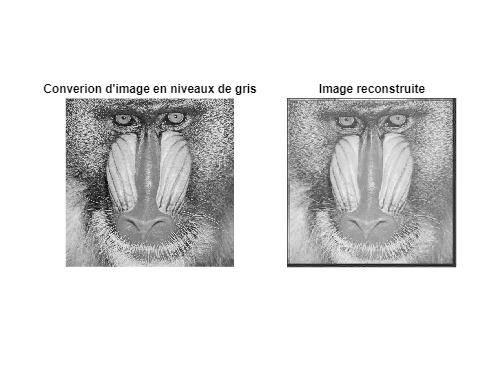

% Chargement de l'mage
imgBaboonRGB = imread('BaboonRGB.bmp');

% Convertir l'image imgBaboonRGB en niveaux de gris
imgBaboonGris = rgb2gray(imgBaboonRGB);

% Transformation en ondelettes 2D
[a1, h1, v1, d1] = dwt2(imgBaboonGris, 'db4', 'mode', 'per');

% 2em niveau de transformation
[a2, h2, v2, d2] = dwt2(a1, 'db4', 'mode', 'per');

% Afficher l'image d'origine et l'image reconstruite
subplot(1,2,1), imshow(imgBaboonGris, []), title('Converion d''image en niveaux de gris');
subplot(1,2,2), imshow(idwt2(a2, h2, v2, d2, 'db4', size(imgBaboonGris)), []), title('Image reconstruite');

figure;


**R2/**

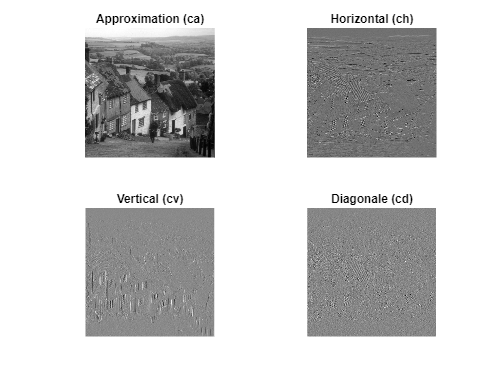

% Charger l'image
imgGoldhill = imread('goldhill.tif');

% Niveau de décomposition
niveau_decomposition = 2;

% Décomposition en utilisant un filtre ondelette 'haar'
[ca, ch, cv, cd] = dwt2(imgGoldhill, 'haar', 'mode', 'per', niveau_decomposition);

% Reconstruction en utilisant la transformation inverse
img_reconstruite = idwt2(ca, ch, cv, cd, 'haar', size(imgGoldhill) * 2);

% Convertir les images en int8 avant de calculer l'erreur
imgGoldhill = int8(imgGoldhill);
img_reconstruite = int8(img_reconstruite);

% Calcul de l'erreur de reconstruction
erreur = imgGoldhill - img_reconstruite; 


% Afficher les sous-bandes obtenues
subplot(2, 2, 1), imshow(ca, []), title('Approximation (ca)');
subplot(2, 2, 2), imshow(ch, []), title('Horizontal (ch)');
subplot(2, 2, 3), imshow(cv, []), title('Vertical (cv)');
subplot(2, 2, 4), imshow(cd, []), title('Diagonale (cd)');

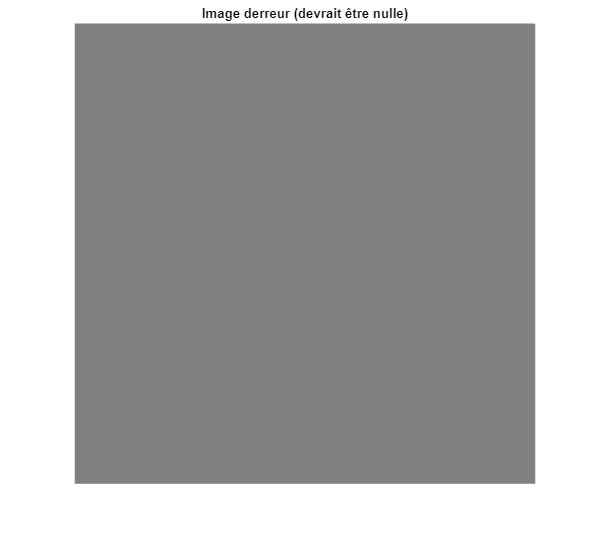


% Afficher l'image d'erreur (devrait être nulle si la reconstruction est parfaite)
figure;
imshow(erreur, []);
title('Image derreur (devrait être nulle)');

**R3/**

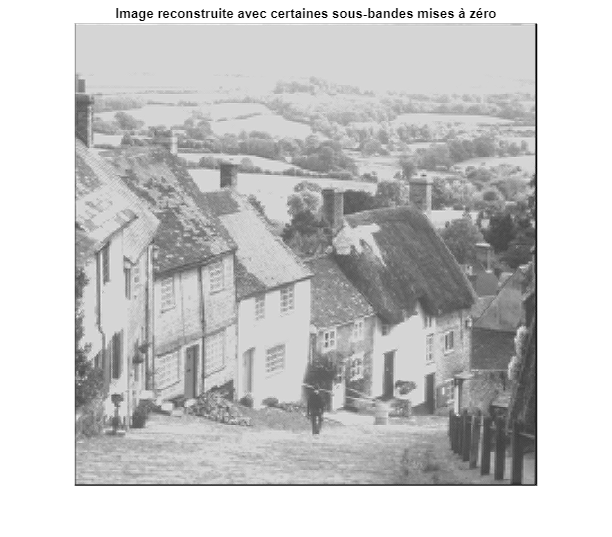


% Décomposition en utilisant un filtre ondelette sym2
[ca, ch, cv, cd] = dwt2(imgGoldhill, 'sym2', 'mode', 'per', niveau_decomposition);

% Quantifier tous les coefficients à l'entier
ca_quantifie = round(ca);
ch_quantifie = round(ch);
cv_quantifie = round(cv);
cd_quantifie = round(cd);

% Mettre à zéro les sous-bandes horizontales et verticales

ch_quantifie_ = zeros(size(ch_quantifie));
cv_quantifie_ = zeros(size(cv_quantifie));

% Transformation inverse
img_reconstruite01 = idwt2(ca_quantifie, ch_quantifie_, cv_quantifie_, cd_quantifie, 'sym2', size(imgGoldhill) * 2);

% Affichage de l' l'image reconstruite
imshow(img_reconstruite01, []);
title('Image reconstruite avec certaines sous-bandes mises à zéro');

 En mettant les coefficients d'approximation à zéro, nous éliminons les composantes à basses fréquences de l'image, laissant principalement les détails d'ondelettes à hautes fréquences. Cela peut conduire à une image contenant une quantité significative de détails fins, de textures et de bruit, ce qui rend l'image visuellement difficile à interpréter.

**R4/**

% Convertir les coefficients 'double' dans l'intervalle [0, 1]
ca_double = double(ca_quantifie);
ch_double = double(ch_quantifie);
cv_double = double(cv_quantifie);
cd_double = double(cd_quantifie);

ca_normalized = mat2gray(ca_double); % Utilisez mat2gray() pour normaliser
ch_normalized = mat2gray(ch_double);
cv_normalized = mat2gray(cv_double);
cd_normalized = mat2gray(cd_double);

% Calculer l'entropie de chaque sous-bande
entropie_ca = entropy(ca_normalized);
entropie_ch = entropy(ch_normalized);
entropie_cv = entropy(cv_normalized);
entropie_cd = entropy(cd_normalized);

% Afficher l'entropie de chaque sous-bande
fprintf('Entropie de ca: %f\n', entropie_ca);

Entropie de ca: 6.613181


fprintf('Entropie de ch: %f\n', entropie_ch);

Entropie de ch: 4.349447


fprintf('Entropie de cv: %f\n', entropie_cv);

Entropie de cv: 4.405668


fprintf('Entropie de cd: %f\n', entropie_cd);

Entropie de cd: 3.608050


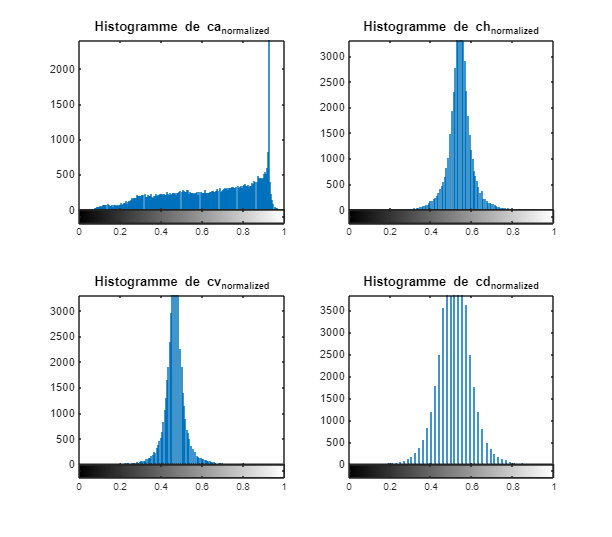


% Sous-plot pour l'histogramme de ca_normalized
subplot(2, 2, 1);
imhist(ca_normalized);
title('Histogramme de ca_normalized');

% Sous-plot pour l'histogramme de ch_normalized
subplot(2, 2, 2);
imhist(ch_normalized);
title('Histogramme de ch_normalized');

% Sous-plot pour l'histogramme de cv_normalized
subplot(2, 2, 3);
imhist(cv_normalized);
title('Histogramme de cv_normalized');

% Sous-plot pour l'histogramme de cd_normalized
subplot(2, 2, 4);
imhist(cd_normalized);
title('Histogramme de cd_normalized');

figure;

L'entropie mesure le niveau d'information ou d'incertitude dans chaque sous-bande. Plus l'entropie est élevée, plus la sous-bande contient d'informations variées et imprévisibles. par exemple la sous-bande ca (approximation) a la plus grande entropie (6.613181), ce qui indique qu'elle contient une grande quantité d'informations ou de variabilité. Cela signifie que les détails globaux de l'image sont contenus dans cette sous-bande. La sous-bande cd (détails diagonaux) a la plus faible entropie (3.608050), ce qui signifie qu'elle contient moins d'informations variées et est probablement plus prévisible.

**R5/**

Les opérations en 3) et 4) sont essentielles pour la compression d'images en ondelettes, car elles permettent de réduire la taille des données tout en préservant la qualité de l'image à un niveau acceptable. L'entropie des sous-bandes aide à déterminer quels éléments d'information sont les plus importants, tandis que la suppression ou la quantification des sous-bandes permet de réduire la taille des données sans perte excessive d'information.

**B- JPEG et JPEG2000**

**R1/**

%Lecture (décodage) 
imageJPG = imread('imgJPG.jpg');
imageJP2 = imread('imgJP2.jp2');

%Écriture (encodage) d'une image en format JPEG 
imwrite(imageJPG, 'nouvelle_imageJPG.jpg', 'jpg');
imwrite(imageJP2, 'nouvelle_imageJP2.jp2', 'jp2');


**R2 & R3/**

 
% Chargement de l'image d'origine
originalImage = imgBaboonRGB; 

% les taux de compression cibles en bpp
targetBPPs = 0.1:0.1:1.0;

% Répéter pour chaque taux de compression cible
for bpp = targetBPPs
    % Compression JPEG
    quality = 100; % Qualité maximale pour commencer
    while true
        % Essayez différentes qualités pour atteindre le taux de compression cible
        compressedImage = imresize(originalImage, 0.5); % Redimensionnez l'image si nécessaire
        imwrite(compressedImage, 'temp.jpg', 'Quality', quality);
        fileInfo = dir('temp.jpg');
        compressedBPP = fileInfo.bytes * 8 / (size(originalImage, 1) * size(originalImage, 2));
        
        if compressedBPP <= bpp
            break;
        end
        
        % Réduisez la qualité si le taux de compression est élevé
        quality = quality - 5;
    end
    %sauvegardez l'image compressée JPEG
    imwrite(compressedImage, ['jpeg_compression_' num2str(bpp) 'bpp.jpg']);
    
    % Calcul du débit binaire (en bpp) de l'image compressée JPEG
    compressedFileInfo = dir(['jpeg_compression_' num2str(bpp) 'bpp.jpg']);
    compressedFileSize = compressedFileInfo.bytes * 8; % en bits
    bpp_jpeg = compressedFileSize / (size(compressedImage, 1) * size(compressedImage, 2));
    
    % Taux de compression correspondant pour JPEG
    compression_ratio_jpeg = size(originalImage, 1) * size(originalImage, 2) / compressedFileSize;
    
    fprintf('Pour la compression JPEG avec %.1f bpp :\n', bpp);
    fprintf('Débit binaire de l''image compressée : %.2f bpp\n', bpp_jpeg);
    fprintf('Taux de compression correspondant : %.2f\n', compression_ratio_jpeg);
    
    % Compression JPEG2000
    % Utilisez 'jp2' comme format
    imwrite(compressedImage, ['jpeg2000_compression_' num2str(bpp) 'bpp.jp2'], 'jp2');
    
    % Calcul du débit binaire (en bpp) de l'image compressée JPEG2000
    jp2FileInfo = dir(['jpeg2000_compression_' num2str(bpp) 'bpp.jp2']);
    jp2FileSize = jp2FileInfo.bytes * 8; % en bits
    bpp_jp2 = jp2FileSize / (size(compressedImage, 1) * size(compressedImage, 2));
    
    % Taux de compression correspondant pour JPEG2000
    compression_ratio_jp2 = size(originalImage, 1) * size(originalImage, 2) / jp2FileSize;
    
    fprintf('Pour la compression JPEG2000 avec %.1f bpp :\n', bpp);
    fprintf('Débit binaire de l''image compressée : %.2f bpp\n', bpp_jp2);
    fprintf('Taux de compression correspondant : %.2f\n', compression_ratio_jp2);
end

Pour la compression JPEG avec 0.1 bpp :


Débit binaire de l'image compressée : 2.29 bpp


Taux de compression correspondant : 1.74


Pour la compression JPEG2000 avec 0.1 bpp :


Débit binaire de l'image compressée : 13.97 bpp


Taux de compression correspondant : 0.29


Pour la compression JPEG avec 0.2 bpp :


Débit binaire de l'image compressée : 2.29 bpp


Taux de compression correspondant : 1.74


Pour la compression JPEG2000 avec 0.2 bpp :


Débit binaire de l'image compressée : 13.97 bpp


Taux de compression correspondant : 0.29


Pour la compression JPEG avec 0.3 bpp :


Débit binaire de l'image compressée : 2.29 bpp


Taux de compression correspondant : 1.74


Pour la compression JPEG2000 avec 0.3 bpp :


Débit binaire de l'image compressée : 13.97 bpp


Taux de compression correspondant : 0.29


Pour la compression JPEG avec 0.4 bpp :


Débit binaire de l'image compressée : 2.29 bpp


Taux de compression correspondant : 1.74


Pour la compression JPEG2000 avec 0.4 bpp :


Débit binaire de l'image compressée : 13.97 bpp


Taux de compression correspondant : 0.29


Pour la compression JPEG avec 0.5 bpp :


Débit binaire de l'image compressée : 2.29 bpp


Taux de compression correspondant : 1.74


Pour la compression JPEG2000 avec 0.5 bpp :


Débit binaire de l'image compressée : 13.97 bpp


Taux de compression correspondant : 0.29


Pour la compression JPEG avec 0.6 bpp :


Débit binaire de l'image compressée : 2.29 bpp


Taux de compression correspondant : 1.74


Pour la compression JPEG2000 avec 0.6 bpp :


Débit binaire de l'image compressée : 13.97 bpp


Taux de compression correspondant : 0.29


Pour la compression JPEG avec 0.7 bpp :


Débit binaire de l'image compressée : 2.29 bpp


Taux de compression correspondant : 1.74


Pour la compression JPEG2000 avec 0.7 bpp :


Débit binaire de l'image compressée : 13.97 bpp


Taux de compression correspondant : 0.29


Pour la compression JPEG avec 0.8 bpp :


Débit binaire de l'image compressée : 2.29 bpp


Taux de compression correspondant : 1.74


Pour la compression JPEG2000 avec 0.8 bpp :


Débit binaire de l'image compressée : 13.97 bpp


Taux de compression correspondant : 0.29


Pour la compression JPEG avec 0.9 bpp :


Débit binaire de l'image compressée : 2.29 bpp


Taux de compression correspondant : 1.74


Pour la compression JPEG2000 avec 0.9 bpp :


Débit binaire de l'image compressée : 13.97 bpp


Taux de compression correspondant : 0.29


Pour la compression JPEG avec 1.0 bpp :


Débit binaire de l'image compressée : 2.29 bpp


Taux de compression correspondant : 1.74


Pour la compression JPEG2000 avec 1.0 bpp :


Débit binaire de l'image compressée : 13.97 bpp


Taux de compression correspondant : 0.29



% Supprimez les fichiers temporaires
delete('temp.jpg');



**R4/**



% Chargement de l'image d'origine
originalImage = imgBaboonRGB;

% Obtenir les dimensions de l'image d'origine
[originalHeight, originalWidth, ~] = size(originalImage);

% les taux de compression cibles en bpp
targetBPPs = 0.1:0.1:1.0;

% Répéter pour chaque taux de compression cible
for bpp = targetBPPs
    % Compression JPEG
    quality = 100; % Qualité maximale pour commencer
    while true
        % Essayez différentes qualités pour atteindre le taux de compression cible
        compressedImage = imresize(originalImage, 0.5); % Redimensionnez l'image si nécessaire
        imwrite(compressedImage, 'temp.jpg', 'Quality', quality);
        fileInfo = dir('temp.jpg');
        compressedBPP = fileInfo.bytes * 8 / (originalHeight * originalWidth);

        if compressedBPP <= bpp
            break;
        end

        % Réduisez la qualité si le taux de compression est élevé
        quality = quality - 5;
    end
    % Sauvegardez l'image compressée JPEG
    imwrite(compressedImage, ['jpeg_compression_' num2str(bpp) 'bpp.jpg']);

    % Compression JPEG2000
    % Utilisez 'jp2' comme format
    imwrite(originalImage, ['jpeg2000_compression_' num2str(bpp) 'bpp.jp2'], 'jp2');
    
    % Lecture de l'image compressée JPEG
    compressedImageJPEG = imread(['jpeg_compression_' num2str(bpp) 'bpp.jpg']);
    
    % Redimensionner l'image compressée JPEG pour qu'elle ait la même taille que l'original
    compressedImageJPEG = imresize(compressedImageJPEG, [originalHeight, originalWidth]);
    
    % Calcul du MSE entre l'image originale et l'image JPEG décodée
    mseJPEG = immse(originalImage, compressedImageJPEG);

    % Calcul du RMSE en prenant la racine carrée du MSE
    rmseJPEG = sqrt(mseJPEG);

    fprintf('Pour la compression JPEG avec %.1f bpp :\n', bpp);
    fprintf('Débit binaire de l''image compressée : %.2f bpp\n', bpp);
    fprintf('MSE (JPEG) : %.2f\n', mseJPEG);
    fprintf('RMSE (JPEG) : %.2f\n', rmseJPEG);

    % Lecture de l'image compressée JPEG2000
    compressedImageJP2 = imread(['jpeg2000_compression_' num2str(bpp) 'bpp.jp2']);
    
    % Redimensionner l'image compressée JPEG2000 pour qu'elle ait la même taille que l'original
    compressedImageJP2 = imresize(compressedImageJP2, [originalHeight, originalWidth]);

    % Calcul du MSE entre l'image originale et l'image JPEG2000 décodée
    mseJP2 = immse(originalImage, compressedImageJP2);

    % Calcul du RMSE en prenant la racine carrée du MSE
    rmseJP2 = sqrt(mseJP2);

    fprintf('Pour la compression JPEG2000 avec %.1f bpp :\n', bpp);
    fprintf('Débit binaire de l''image compressée : %.2f bpp\n', bpp);
    fprintf('MSE (JPEG2000) : %.2f\n', mseJP2);
    fprintf('RMSE (JPEG2000) : %.2f\n', rmseJP2);
end

Pour la compression JPEG avec 0.1 bpp :


Débit binaire de l'image compressée : 0.10 bpp


MSE (JPEG) : 427.08


RMSE (JPEG) : 20.67


Pour la compression JPEG2000 avec 0.1 bpp :


Débit binaire de l'image compressée : 0.10 bpp


MSE (JPEG2000) : 0.45


RMSE (JPEG2000) : 0.67


Pour la compression JPEG avec 0.2 bpp :


Débit binaire de l'image compressée : 0.20 bpp


MSE (JPEG) : 427.08


RMSE (JPEG) : 20.67


Pour la compression JPEG2000 avec 0.2 bpp :


Débit binaire de l'image compressée : 0.20 bpp


MSE (JPEG2000) : 0.45


RMSE (JPEG2000) : 0.67


Pour la compression JPEG avec 0.3 bpp :


Débit binaire de l'image compressée : 0.30 bpp


MSE (JPEG) : 427.08


RMSE (JPEG) : 20.67


Pour la compression JPEG2000 avec 0.3 bpp :


Débit binaire de l'image compressée : 0.30 bpp


MSE (JPEG2000) : 0.45


RMSE (JPEG2000) : 0.67


Pour la compression JPEG avec 0.4 bpp :


Débit binaire de l'image compressée : 0.40 bpp


MSE (JPEG) : 427.08


RMSE (JPEG) : 20.67


Pour la compression JPEG2000 avec 0.4 bpp :


Débit binaire de l'image compressée : 0.40 bpp


MSE (JPEG2000) : 0.45


RMSE (JPEG2000) : 0.67


Pour la compression JPEG avec 0.5 bpp :


Débit binaire de l'image compressée : 0.50 bpp


MSE (JPEG) : 427.08


RMSE (JPEG) : 20.67


Pour la compression JPEG2000 avec 0.5 bpp :


Débit binaire de l'image compressée : 0.50 bpp


MSE (JPEG2000) : 0.45


RMSE (JPEG2000) : 0.67


Pour la compression JPEG avec 0.6 bpp :


Débit binaire de l'image compressée : 0.60 bpp


MSE (JPEG) : 427.08


RMSE (JPEG) : 20.67


Pour la compression JPEG2000 avec 0.6 bpp :


Débit binaire de l'image compressée : 0.60 bpp


MSE (JPEG2000) : 0.45


RMSE (JPEG2000) : 0.67


Pour la compression JPEG avec 0.7 bpp :


Débit binaire de l'image compressée : 0.70 bpp


MSE (JPEG) : 427.08


RMSE (JPEG) : 20.67


Pour la compression JPEG2000 avec 0.7 bpp :


Débit binaire de l'image compressée : 0.70 bpp


MSE (JPEG2000) : 0.45


RMSE (JPEG2000) : 0.67


Pour la compression JPEG avec 0.8 bpp :


Débit binaire de l'image compressée : 0.80 bpp


MSE (JPEG) : 427.08


RMSE (JPEG) : 20.67


Pour la compression JPEG2000 avec 0.8 bpp :


Débit binaire de l'image compressée : 0.80 bpp


MSE (JPEG2000) : 0.45


RMSE (JPEG2000) : 0.67


Pour la compression JPEG avec 0.9 bpp :


Débit binaire de l'image compressée : 0.90 bpp


MSE (JPEG) : 427.08


RMSE (JPEG) : 20.67


Pour la compression JPEG2000 avec 0.9 bpp :


Débit binaire de l'image compressée : 0.90 bpp


MSE (JPEG2000) : 0.45


RMSE (JPEG2000) : 0.67


Pour la compression JPEG avec 1.0 bpp :


Débit binaire de l'image compressée : 1.00 bpp


MSE (JPEG) : 427.08


RMSE (JPEG) : 20.67


Pour la compression JPEG2000 avec 1.0 bpp :


Débit binaire de l'image compressée : 1.00 bpp


MSE (JPEG2000) : 0.45


RMSE (JPEG2000) : 0.67



% Supprimez les fichiers temporaires
delete('temp.jpg');



**R5/**

Comme commentaire un taux de compression aussi bas que 0.1 bpp, vous pouvez vous attendre à une qualité d'image relativement élevée pour les deux codecs, bien que JPEG2000 puisse offrir une meilleure qualité subjective à des taux de compression similaires par rapport à JPEG.